data1 = data(:,1);
data2 = data(:,2);

y1 = downsample(data1,3);
y2 = downsample(data2,3);

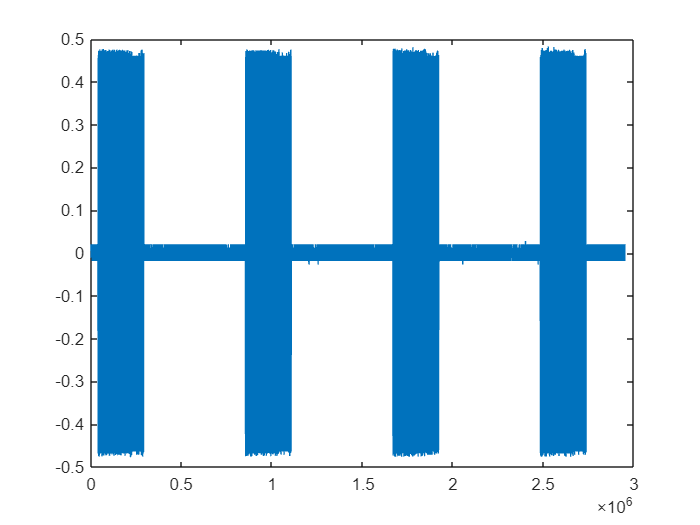

plot(y1);

plot(y2);

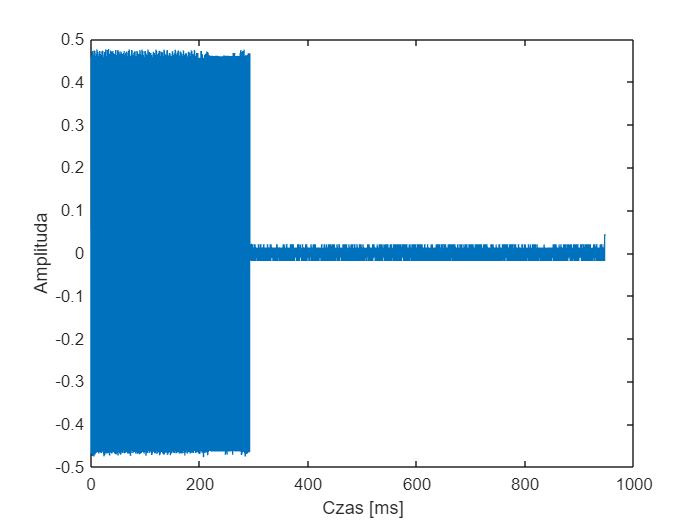

y1_cut = y1(39588:853952,1);
y2_cut = y2(39588:853952,1);

N = length(y1_cut);              % liczba próbek
t = linspace(0, 946, N);        % wektor czasu od 0 do 1000 ms

plot(t,y1_cut)
xlabel('Czas [ms]');
ylabel('Amplituda');

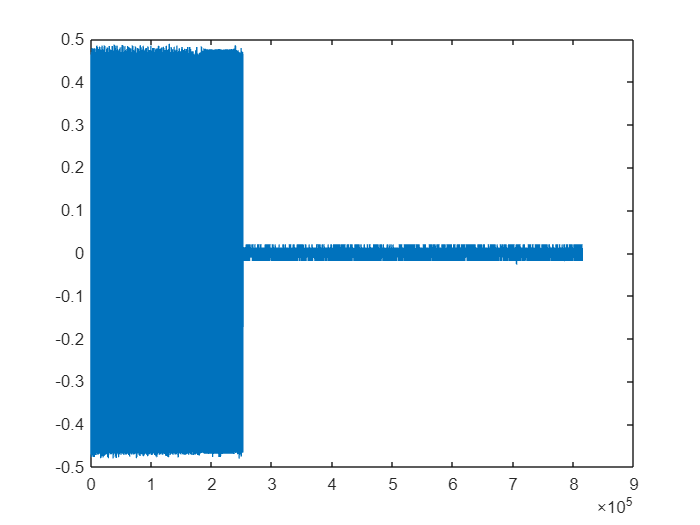

plot(y2_cut)

%39588
%251634
%853952

%1 - 212 046 - 26%
%0 - 602 318 - 74% - 700 ms
%10 - 814 364 - 100% - 946 ms

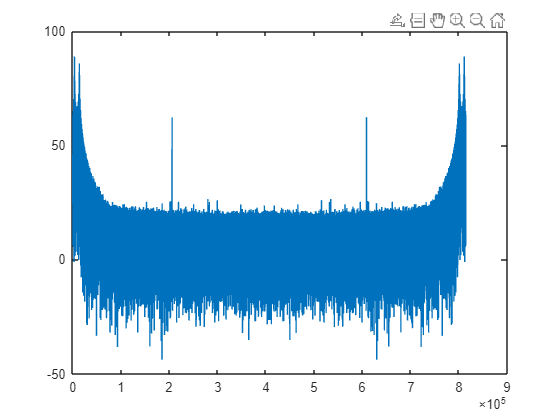

widmo = 20*log10(abs(fft(y1_cut)));
plot(widmo)

widmo_cut = widmo(1:814364,1);
l = length(widmo_cut);
half = l/2;
widmo_swapped = [widmo_cut((half)+1:end), widmo_cut(1:(half))];

Fs = 2.4e6;              % Częstotliwość próbkowania
Fc = 433e6;              % Częstotliwość nośna
y = y1_cut;              % Twój sygnał

N = length(y);
Y = fft(y);
Y_mag = 20*log10(abs(Y(1:N/2)));           % Połowa widma w dB

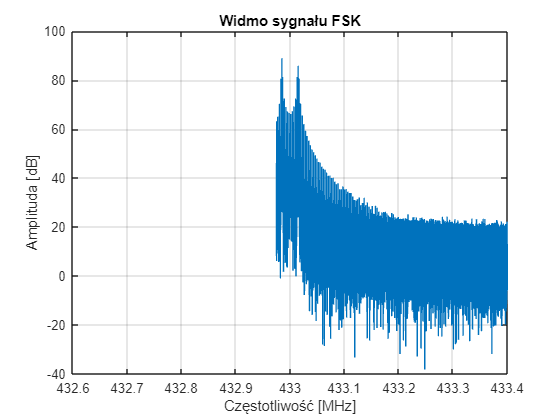


% Oś częstotliwości: od 432.975 MHz do 432.975 MHz + Fs/2
f_start = 432.975e6;
f = linspace(f_start, f_start + Fs/2, N/2); % w Hz
f_MHz = f / 1e6;                             % w MHz

% Wykres
plot(f_MHz, Y_mag);
xlabel('Częstotliwość [MHz]');
ylabel('Amplituda [dB]');
title('Widmo sygnału FSK');
xlim([432.6 433.4]);                         % Zakres wokół pasma ISM
grid on;

Fs = 2.4e6;              % Częstotliwość próbkowania
Fc = 433e6;              % Częstotliwość nośna
y = y1_cut;              % Twój sygnał

N = length(y);
Y = fft(y);
Y_mag = 20*log10(abs(Y(1:N/2)));           % Połowa widma w dB

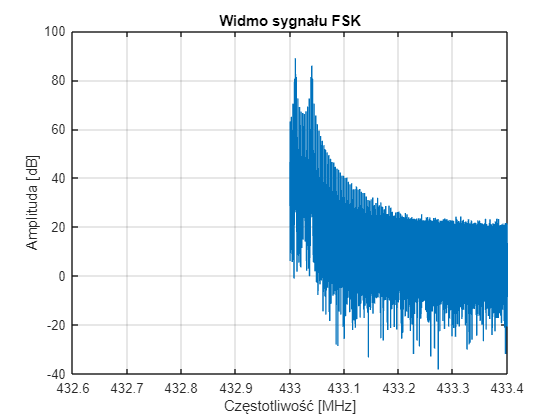


% Oś częstotliwości: od Fc do Fc + Fs/2
f = linspace(Fc, Fc + Fs/2, N/2);          % w Hz
f_MHz = f / 1e6;                           % w MHz

% Wykres
plot(f_MHz, Y_mag);
xlabel('Częstotliwość [MHz]');
ylabel('Amplituda [dB]');
title('Widmo sygnału FSK');
xlim([432.6 433.4]);                       % Zakres wokół pasma ISM
grid on;